% exam sept 2017

THIS CODE MUST BE FIXED

l1 = 0.5

l1 = 0.5000

l2 = 0.5

l2 = 0.5000

q1_2_in = [45, -90]'

q1_2_in =     45
   -90


p_goal = [0.5, 0.866]'

p_goal =     0.5000
    0.8660



vin = 0

vin = 0

vfin = 0

vfin = 0

rob = robot_planar_2R();
[q1_fin, q2_fin] = rob.inverse(l1, l2, p_goal, 'pos')

q1_fin = 1.0406

q2_fin = 0.0133

q1_fin = rad2deg(q1_fin)

q1_fin = 59.6192

q2_fin = rad2deg(q2_fin)

q2_fin = 0.7601

% Q1
qin = q1_2_in(1)

qin = 45

qfin = q1_fin

qfin = 59.6192


syms t T positive real
tau = t/T;
[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, true)

##############################################################
Cubic Polynomial Double Normalized (tau belongs to [0, 1])

$$q\_tau = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$

Where Dq = (qfin - qin)---------------------------------------------------------
Equations:

$$eq\_1 = d=0$$

$$eq\_2 = a+b+c=1$$

$$eq\_3 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$eq\_4 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$

---------------------------------------------------------
Symbolic solutions:

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

$$d = 0$$

---------------------------------------------------------
Numerical solutions:


$$a = -2$$

$$b = 3$$

$$c = 0$$

$$d = 0$$

##############################################################


$$a = -2$$

$$b = 3$$

$$c = 0$$

$$d = 0$$

q1_t = cubic_poly_double_norm(a, b, c, d, tau, qin, qfin)

$$q1\_t = \frac{3086206815757659\,t^{2}}{70368744177664\,T^{2}}-\frac{1028735605252553\,t^{3}}{35184372088832\,T^{3}}+45$$

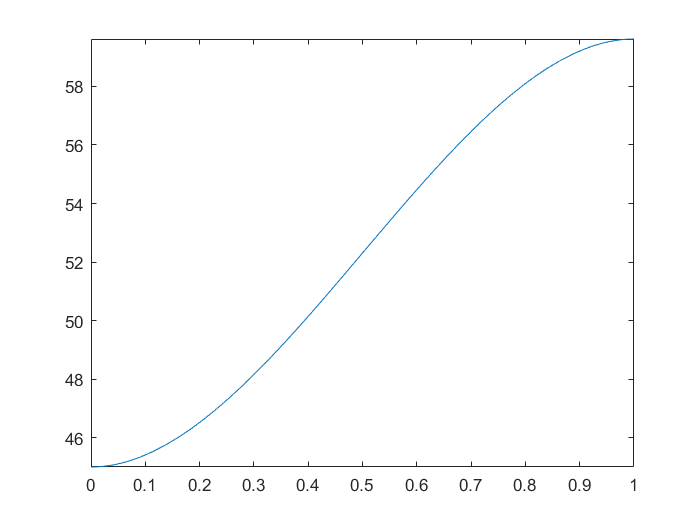

plot_function(subs(q1_t, {T}, {1}), t, [0, 1])

q1_dot = diff(q1_t, t)

$$q1\_dot = \frac{3086206815757659\,t}{35184372088832\,T^{2}}-\frac{3086206815757659\,t^{2}}{35184372088832\,T^{3}}$$

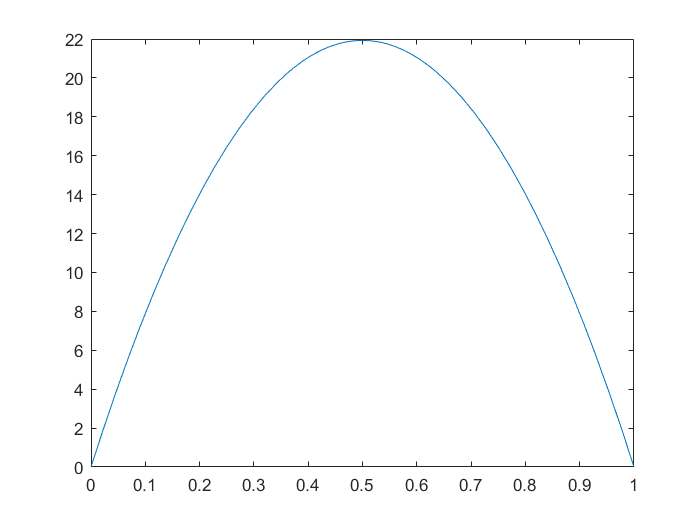

plot_function(subs(q1_dot, {T}, {1}), t, [0, 1])


[x, y] = find_sym_abs_max_in_positive_interval(q1_dot, T, t, T)

$$x = \frac{T}{2}$$

$$y = \frac{3086206815757659}{140737488355328\,T}$$

q1_dd = diff(q1_dot, t)

$$q1\_dd = \frac{3086206815757659}{35184372088832\,T^{2}}-\frac{3086206815757659\,t}{17592186044416\,T^{3}}$$

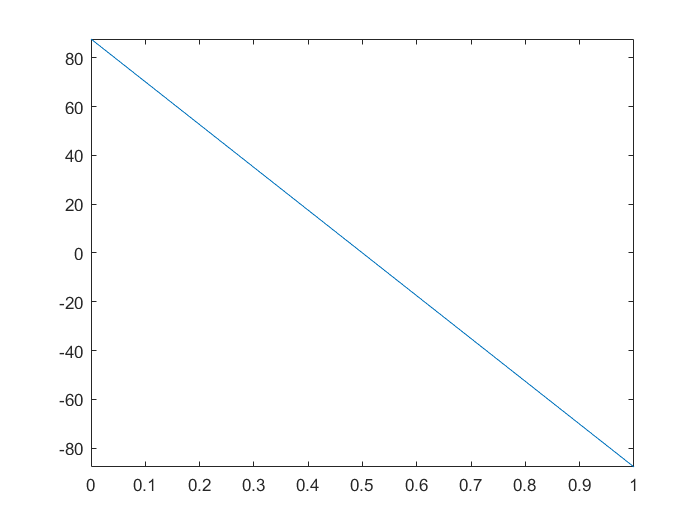

plot_function(subs(q1_dd, {T}, {1}), t, [0, 1])


[x, y] = find_sym_abs_max_in_positive_interval(q1_dd, T, t, T)

x = 0

$$y = \frac{3086206815757659}{35184372088832\,T^{2}}$$

eq = subs(q1_dot, {t}, {T/2}) == 30

$$eq = \frac{3086206815757659}{140737488355328\,T}=30$$

s1 = eval(solve(eq, T))

s1 = 0.7310

% Q2
qin = q1_2_in(2)

qin = -90

qfin = q2_fin

qfin = 0.7601


syms t T positive real
tau = t/T;
[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, false)

$$a = -2$$

$$b = 3$$

$$c = 0$$

$$d = 0$$

q2_t = cubic_poly_double_norm(a, b, c, d, tau, qin, qfin)

$$q2\_t = \frac{19160026994306571\,t^{2}}{70368744177664\,T^{2}}-\frac{6386675664768857\,t^{3}}{35184372088832\,T^{3}}-90$$

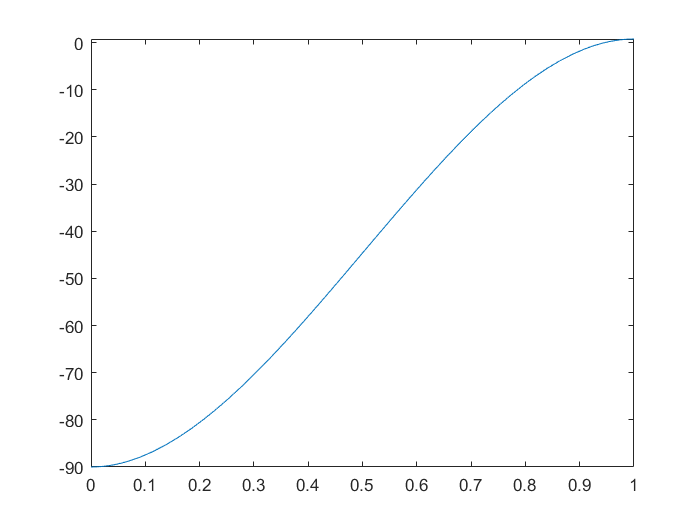

plot_function(subs(q2_t, {T}, {1}), t, [0, 1])

q2_dot = diff(q2_t, t)

$$q2\_dot = \frac{19160026994306571\,t}{35184372088832\,T^{2}}-\frac{19160026994306571\,t^{2}}{35184372088832\,T^{3}}$$

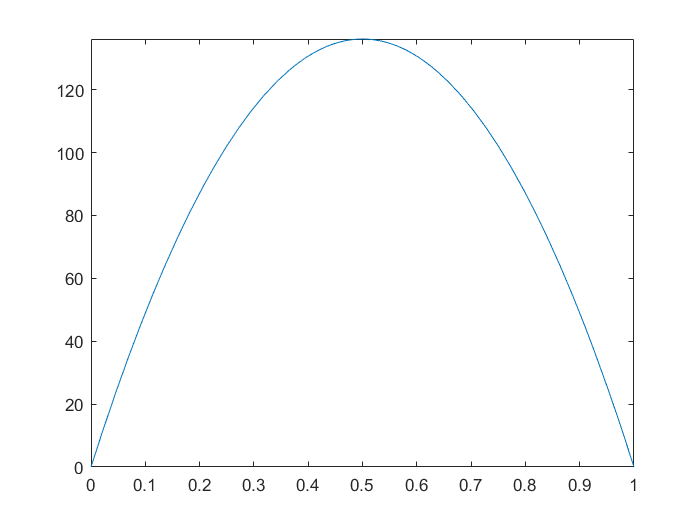

plot_function(subs(q2_dot, {T}, {1}), t, [0, 1])


[x, y] = find_sym_abs_max_in_positive_interval(q2_dot, T, t, T)

$$x = \frac{T}{2}$$

$$y = \frac{19160026994306571}{140737488355328\,T}$$

q2_dd = diff(q2_dot, t)

$$q2\_dd = \frac{19160026994306571}{35184372088832\,T^{2}}-\frac{19160026994306571\,t}{17592186044416\,T^{3}}$$

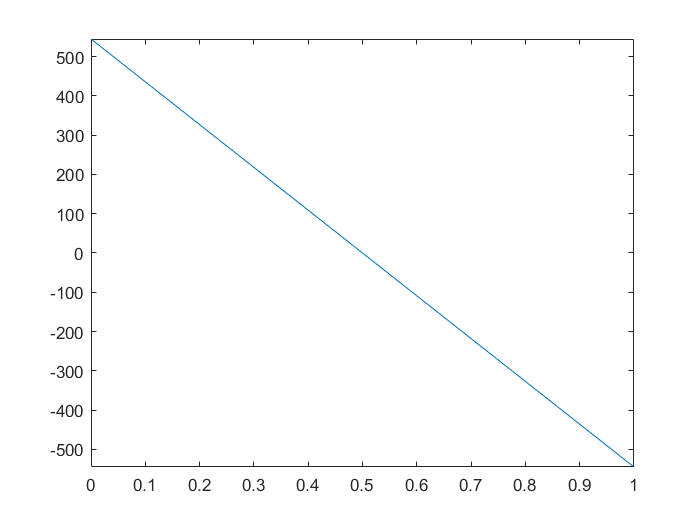

plot_function(subs(q2_dd, {T}, {1}), t, [0, 1])


[x, y] = find_sym_abs_max_in_positive_interval(q2_dd, T, t, T)

x = 0

$$y = \frac{19160026994306571}{35184372088832\,T^{2}}$$

eq = subs(q2_dot, {t}, {T/2}) == 90

$$eq = \frac{19160026994306571}{140737488355328\,T}=90$$

s2 = eval(solve(eq, T))

s2 = 1.5127

%Q1
qin = q1_2_in(1)

qin = 45

qfin = q1_fin

qfin = 59.6192


syms t  positive real

T = s1

T = 0.7310

tau = t/T;

[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, false);
q1_t = cubic_poly_double_norm(a, b, c, d, tau, qin, qfin)

$$q1\_t = -\frac{21366002605663021850082326897035108304606411620352\,t^{3}}{285398204096346591805002381020610446146263966219}+\frac{1186051401850408795750753504329728\,t^{2}}{14449280962755740839484589254307}+45$$

q1_dot = diff(q1_t, t)

$$q1\_dot = \frac{2372102803700817591501507008659456\,t}{14449280962755740839484589254307}-\frac{21366002605663021850082326897035108304606411620352\,t^{2}}{95132734698782197268334127006870148715421322073}$$

q1_dd = diff(q1_dot, t)

$$q1\_dd = \frac{2372102803700817591501507008659456}{14449280962755740839484589254307}-\frac{42732005211326043700164653794070216609212823240704\,t}{95132734698782197268334127006870148715421322073}$$


%Q2
qin = q1_2_in(2)

qin = -90

qfin = q2_fin

qfin = 0.7601


syms t  positive real

T = max(s1, s2);
tau = t/T;

[a, b, c, d] = cubic_poly_double_norm_compute_coeff(qin, qfin, vin, vfin, T, false);
q2_t = cubic_poly_double_norm(a, b, c, d, tau, qin, qfin)

$$q2\_t = -\frac{2072594749416260506083316559603774439946182459392\,t^{3}}{39520348850112598242338934443532122536834055193}+\frac{460208482303827827416168663089152\,t^{2}}{3867460840007179366581505981083}-90$$

q2_dot = diff(q2_t, t)

$$q2\_dot = \frac{920416964607655654832337326178304\,t}{3867460840007179366581505981083}-\frac{2072594749416260506083316559603774439946182459392\,t^{2}}{13173449616704199414112978147844040845611351731}$$

q2_dd = diff(q2_dot, t)

$$q2\_dd = \frac{920416964607655654832337326178304}{3867460840007179366581505981083}-\frac{4145189498832521012166633119207548879892364918784\,t}{13173449616704199414112978147844040845611351731}$$

% pos 
q_t = [q1_t, q2_t]'

$$q\_t = \left(\begin{array}{c} -\frac{21366002605663021850082326897035108304606411620352\,t^{3}}{285398204096346591805002381020610446146263966219}+\frac{1186051401850408795750753504329728\,t^{2}}{14449280962755740839484589254307}+45\\ -\frac{2072594749416260506083316559603774439946182459392\,t^{3}}{39520348850112598242338934443532122536834055193}+\frac{460208482303827827416168663089152\,t^{2}}{3867460840007179366581505981083}-90 \end{array}\right)$$

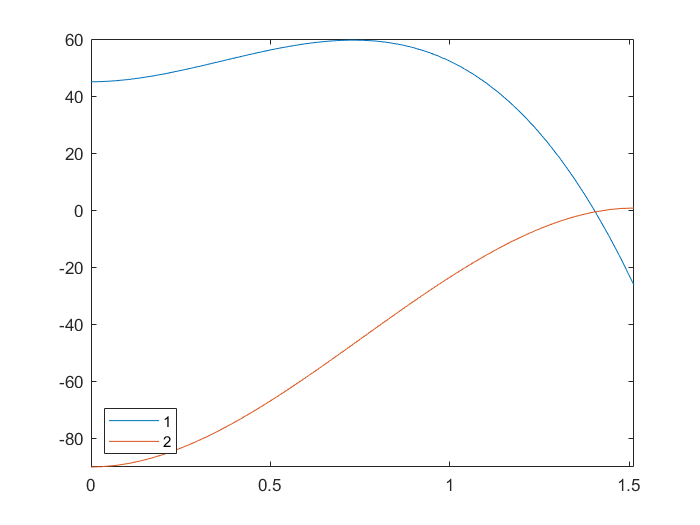

----------------------------------
START AT:
    45

END AT:
  -26.3002

----------------------------------
----------------------------------
START AT:
   -90

END AT:
    0.7601

----------------------------------


plot_function_check_start_end(q_t, t, [0, T])

%vel
q_dot = [q1_dot, q2_dot]'

$$q\_dot = \left(\begin{array}{c} \frac{2372102803700817591501507008659456\,t}{14449280962755740839484589254307}-\frac{21366002605663021850082326897035108304606411620352\,t^{2}}{95132734698782197268334127006870148715421322073}\\ \frac{920416964607655654832337326178304\,t}{3867460840007179366581505981083}-\frac{2072594749416260506083316559603774439946182459392\,t^{2}}{13173449616704199414112978147844040845611351731} \end{array}\right)$$

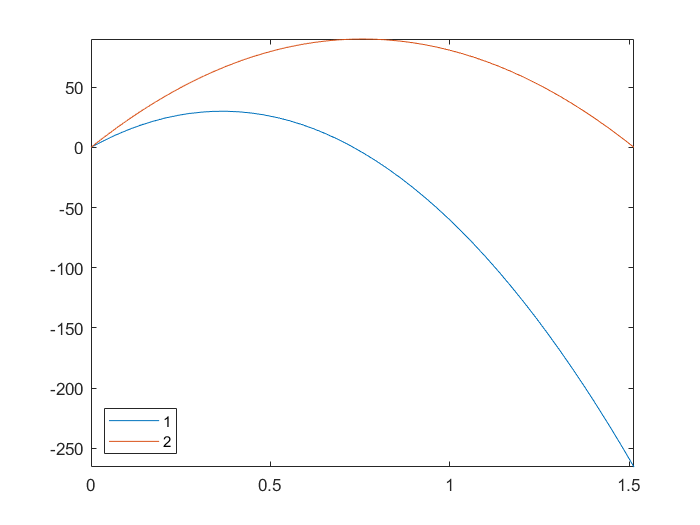

----------------------------------
START AT:
     0

END AT:
 -265.5716

----------------------------------
----------------------------------
START AT:
     0

END AT:
     0

----------------------------------


plot_function_check_start_end(q_dot, t, [0, T])

[x, q1_dot_max] = find_abs_maximum_function(q1_dot, t)

x = 0.3655

q1_dot_max = 30

[x, q2_dot_max] = find_abs_maximum_function(q2_dot, t)

x = 0.7563

q2_dot_max = 90